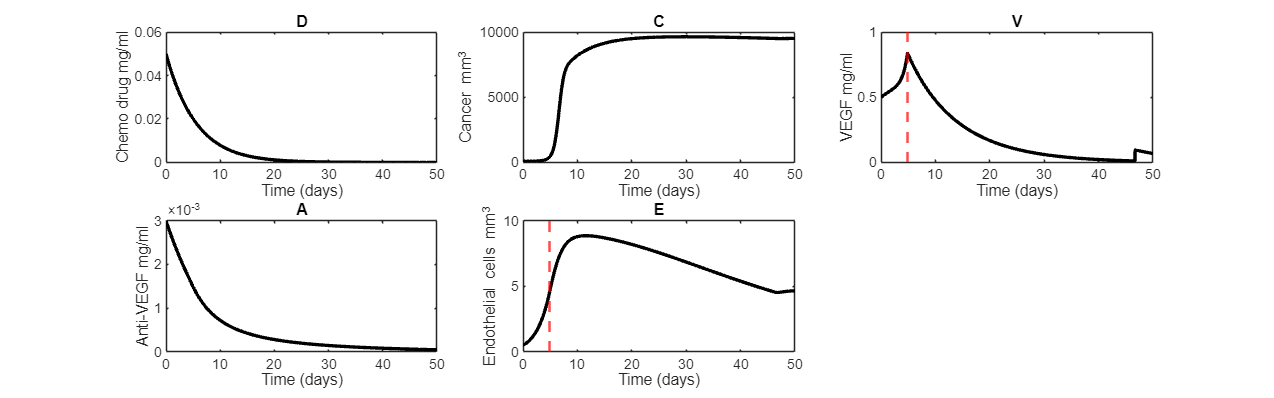

% Load these variables/parameters %
G = [10^4, 10]; %CM and EM
d = [0.103, 0.1825, 0.05, 0.1, 0.05, 0.1685, 1.0839*(10^(-6)), 0.4579, 0.03, 10^(-3),10, 0.15]; %original
%   dc      dd      de     dv   db      b           bk           l.ce  l.e   l.v0    uB   uBK
Ethres = 4.5;
k = 1;
D0 = 0.05; %0.002 - 0.05
C0 = 100;
E0 = 0.5; %0.5 - 3
V0 = 0.5;
A0 = 0.003; %0.003-0.07
x0 = [D0,C0, V0, A0, E0];
[T,Y] = ode15s(@ODEBreastCancerModel,[0,50], x0,[],d,k,G);

Thresbool = T(Y(:,5) > Ethres);
if isempty(Thresbool)
    T_thres_pass = 0;
else
    T_thres_pass = Thresbool(1); %first timepoint where > Ethres
end

%plot
figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.5]);

subplot(2,3,1);
plot(T, Y(:,1), 'k-','linewidth',2);
title("D");
xlabel("Time (days)")
ylabel("Chemo drug mg/ml")

subplot(2,3,2);
plot(T, Y(:,2), 'k-','linewidth',2);
title("C");
xlabel("Time (days)")
ylabel("Cancer mm^3")

subplot(2,3,3);
plot(T, Y(:,3), 'k-','linewidth',2);
hold on
xline(T_thres_pass, '--r', 'LineWidth',1.5)
hold off
title("V");
xlabel("Time (days)")
ylabel("VEGF mg/ml")

subplot(2,3,4);
plot(T, Y(:,4), 'k-','linewidth',2);
title("A");
xlabel("Time (days)")
ylabel("Anti-VEGF mg/ml")

subplot(2,3,5)
plot(T, Y(:,5), 'k-','linewidth',2);
hold on
xline(T_thres_pass, '--r', 'LineWidth',1.5)
hold off
title("E");
xlabel("Time (days)")
ylabel("Endothelial cells mm^3")

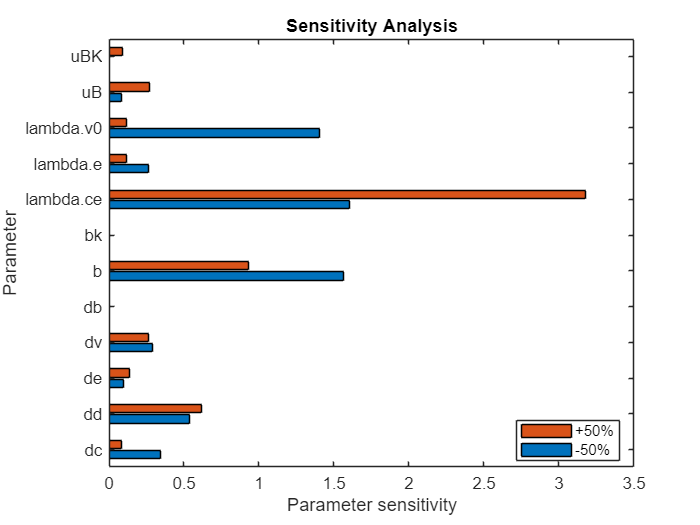

%Run the first simulation section first
sensitivity_factor = 0.5;

[T, Y] = ode15s(@ODEBreastCancerModel, [0,50], x0, [], d, k, G);
C_baseline = Y(round(length(Y)/5), 2); %20th entry in Y

paremeter_count = length(d);
C_plus_50 = zeros(paremeter_count, 1);
C_minus_50 = zeros(paremeter_count, 1);
parameter_sensitivity = zeros(paremeter_count, 1);

for i = 1:paremeter_count
    d_plus = d;
    d_plus(i) = d_plus(i) * (1 + sensitivity_factor);
    [T_plus, Y_plus] = ode15s(@ODEBreastCancerModel, [0,50], x0, [], d_plus, k, G);
    C_plus_50(i) = Y_plus(round(length(Y)/5), 2);

    delta_k = d(i) * sensitivity_factor;
    parameter_sensitivity(i) = abs(((C_plus_50(i) - C_baseline) / C_baseline) * (d(i) / delta_k)); %+50%

    d_minus = d;
    d_minus(i) = d_minus(i) * (1 - sensitivity_factor);
    [T_minus, Y_minus] = ode15s(@ODEBreastCancerModel, [0,50], x0, [], d_minus, k, G);
    C_minus_50(i) = Y_minus(round(length(Y)/5), 2);
    
    parameter_sensitivity(i,2) = abs(((C_minus_50(i) - C_baseline) / C_baseline) * (d(i) / (-delta_k))); %-50%
end

bar_data = [parameter_sensitivity(:,2), parameter_sensitivity(:,1)];
bar_labels = ["dc", "dd", "de", "dv", "db", "b", "bk", "lambda.ce", "lambda.e", "lambda.v0", "uB", "uBK"];

figure;
barh(bar_data);
set(gca, "YTickLabel", bar_labels);
ylabel("Parameter");
xlabel("Parameter sensitivity");
legend({"-50%", "+50%"}, "Location", "Best");
title("Sensitivity Analysis");

function dx = ODEBreastCancerModel(t,x, d, k, G)
% parameters:
dc = d(1);
dd = d(2);
de = d(3);
dv = d(4);
db = d(5);
b = d(6);
bk = d(7);
lambda.ce = d(8);
lambda.e = d(9);
lambda.v0 = d(10);
uB = d(11);
uBk = d(12);
CM = G(1);
EM = G(2);
Ethres = 4.5;
% state variables:
D =x(1);
C =x(2);
V =x(3);
A =x(4);
E =x(5);
% calculate derivatives based on ODEs:
dx = zeros(5,1);

dx(1) = - dd*D - bk*C*D*(E/EM); %D
dx(2) = (lambda.ce*E)*C*(1 - C/CM) - dc*C - b*D*C*(E/EM); %C

if E < Ethres
    dx(3) = lambda.v0 *C - dv*V - uB*V*A; %V
else
    dx(3) = - dv*V - uB*V*A;
end
dx(4) = - db*A - uBk*V*A; %A
dx(5) = (lambda.e + k*V)*E*(1 - E/EM) - de*E ; %E
end
